clear

addpath("matlab_functions\")

set(groot, 'DefaultAxesFontName', 'Times New Roman')

#### Read MFD data

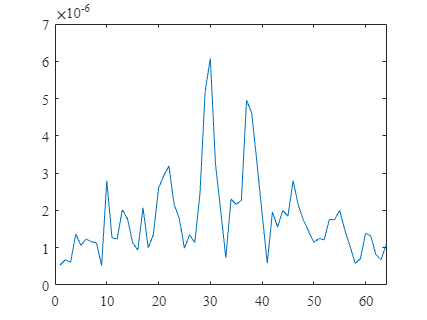

[B0,freqs1,defects] = readMFD('data/B_ec_defectless.txt');
assert(isempty(defects))

[B ,freqs2,defects] = readMFD('data/B_ec_defect_circ4mm.txt');
assert(all(freqs1==freqs2))

freq = freqs1;
delta_B = B - B0;

idx = 1;
freq = freq(idx);
delta_B = delta_B(idx,:).';

c = vecnorm(reshape(delta_B(:,1), 2,[]));
figure
plot(c)

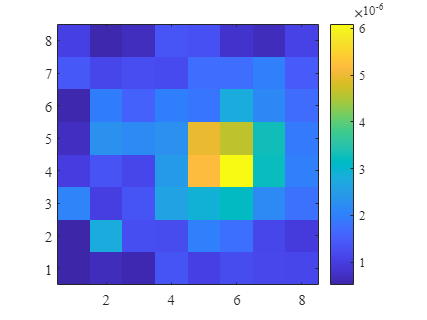

c = reshape(c, 8,8);
figure
imagesc(c.')
colorbar
axis square xy


clear idx freqs1 freqs2 B0 B c

#### Load sensitivity matrix

load(sprintf('data/Sensitivity_%dHz.mat', freq))

xylim = 20e-3;
mask = -xylim < element_centers(1,:) &  element_centers(1,:) < xylim & ...
       -xylim < element_centers(2,:) &  element_centers(2,:) < xylim & element_centers(3,:) > -1.2e-3;

S = S(:, mask);
element_centers = element_centers(:, mask);

S = [real(S); imag(S)];
delta_B = [real(delta_B); imag(delta_B)];

clear xylim mask 

#### Tikhonov regularization


$$\Delta \tilde{\sigma} =\textrm{argmin}\left\lbrace {\left\|S\Delta \sigma -\Delta B\right\|}_2^2 +\lambda {\left\|\Delta \sigma \right\|}_2^2 \right\rbrace$$


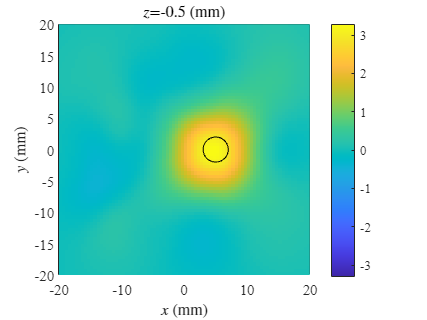

lambda = 1e-20;
R = (S' * S + lambda * eye(size(S,2))) \ S';

delta_sigma = R * delta_B;

displayReconstruction(delta_sigma, element_centers, defects)


clear lambda R delta_sigma

#### Sparsity regularization


$$\Delta \tilde{\sigma} =\textrm{argmin}\left\lbrace {\left\|S\Delta \sigma -\Delta B\right\|}_2^2 +\lambda {\left\|\Delta \sigma \right\|}_1 \right\rbrace$$


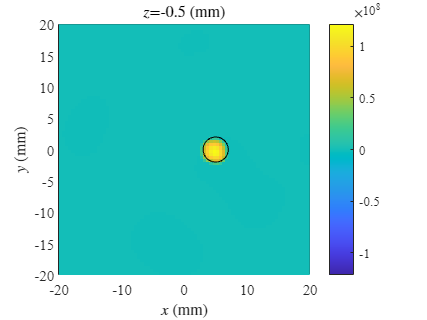

lambda = 1e-20;
beta = 1e-27;

reg{1}.lambda = lambda;
reg{1}.L = speye(size(S,2));

delta_sigma = L1Regularize(S,delta_B, reg, beta);

displayReconstruction(delta_sigma, element_centers, defects)


clear lambda beta reg

#### Sparse Bayesian learning

b = 1;
Psi = ElementsOperation('BlockGroup', element_centers, b,b,1);

tic
delta_sigma = BlockSBL(S*Psi, delta_B, b^2, 'ShareCorrelationMatrix',true, ...
    'MaxIterations',10, 'AmpEstep',true);
delta_sigma = Psi * delta_sigma;
toc

Elapsed time is 1.510459 seconds.


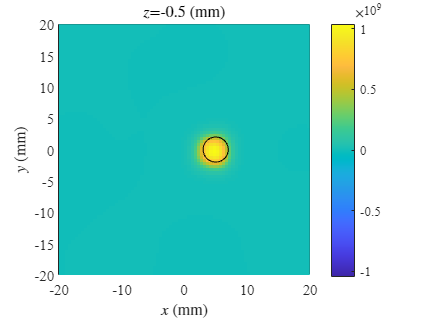


displayReconstruction(delta_sigma, element_centers, defects)


clear b Psi delta_sigma

function [B, freqs, defects] = readMFD(fname)

B = [];
freqs = [];
defects = {};

lines = readlines(fname);

for k = 1:length(lines)
    str = strtrim(lines(k));
    str = convertStringsToChars(str);
    if isempty(str)
        continue
    end

    if ~startsWith(str, '%')
        B(end+1,:) = str2num(str);
    else
        str = strtrim(str(2:end));
        if startsWith(str, 'frequency')
            tokens = split(str);
            freqs(end+1) = str2num(tokens{2});
            assert(strcmp(tokens{3}, "Hz"))
        elseif startsWith(str, 'defect')
            i = strfind(str, ' ');
            defects{end+1} = jsondecode(str(i:end));
        else
            error('Unknown "%s"', str)
        end
    end
end

end

function displayReconstruction(delta_sigma, element_centers, defects)

c = real(-delta_sigma);

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

figure('Position',[10 10 400 300*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    x = [min(element_centers(1,mask)) max(element_centers(1,mask))] * scale;
    y = [min(element_centers(2,mask)) max(element_centers(2,mask))] * scale;

    subplot(length(z),1,k)
    hold on
    imagesc(x, y, c_layer.', [-max(c) max(c)])
    colorbar
    axis square xy
    box on
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')

    for p = 1:length(defects)
        defect = defects{p};
        if ~(min(defect.z1, defect.z2) <= z(k) && z(k) <= max(defect.z1, defect.z2))
            continue
        end
        switch lower(defect.type)
            case 'rectangular'
                rect = [defect.c_x-defect.dx/2 defect.c_y-defect.dy/2 defect.dx defect.dy];
                rectangle('Position', rect * scale)
            case 'circular'
                theta = linspace(0, 2*pi);
                x = defect.c_x + defect.d/2 * cos(theta);
                y = defect.c_y + defect.d/2 * sin(theta);
                plot(x * scale, y * scale, 'k')
            case 'polygonal'
                plot(defect.xs * scale, defect.ys * scale, 'k')
            otherwise
                error('Unknown defect shape "%s"', defect.type)
        end
    end
end

end